# Control statements: How to use the `if` statement?

## Introduction

So far, while writing MATLAB Live Scripts, we’ve been writing commands to be executed one line after another. Unless a line is a comment (denoted by a preceding "`%`"), every line in a script will be executed in order of appearance (sequentially). For example:

x = linspace(0, 1, 100);  %1st, x is a vector of 100 numbers from 0 to 1
y = x.^2 + 1;             %2nd, y is a vector of 100 numbers calculated as x.^2+1
plot(x, y);               %3rd, plots vectors x against y on a graph, and shows it in the Output view
title('Plot of x^2+1');   %4th, adds a title to the plot
xlabel('x');              %5th, adds a label to the x-axis
ylabel('y');              %last, adds a label to the y-axis

Fortunately, in MATLAB Live Scripts we can also make use of **control statements**. These are statements (commands) that will allow you to have total control over the **flow** of the code being executed – maybe you only want particular lines executed in particular situations? Or want to repeat a command over and over again?

The flow of the program (live script) can be changed from just executing lines one-by-one, to skipping or repeating intermediate sets of commands.

More technically, control statements are used to modify the order in which commands are executed by MATLAB, so that we are not restricted to executing commands sequentially. MATLAB provides several types of control statements, including

- [if statements](https://au.mathworks.com/help/matlab/ref/if.html), which execute a set of commands if a given condition is satisfied;

- [for loops](https://au.mathworks.com/help/matlab/ref/for.html), which execute a set of commands a given number of times; and

- [while loops](https://au.mathworks.com/help/matlab/ref/while.html), which execute a set of commands while a given condition is true.

In this activity we will learn how to use the `if` statement.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read carefuly each section. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

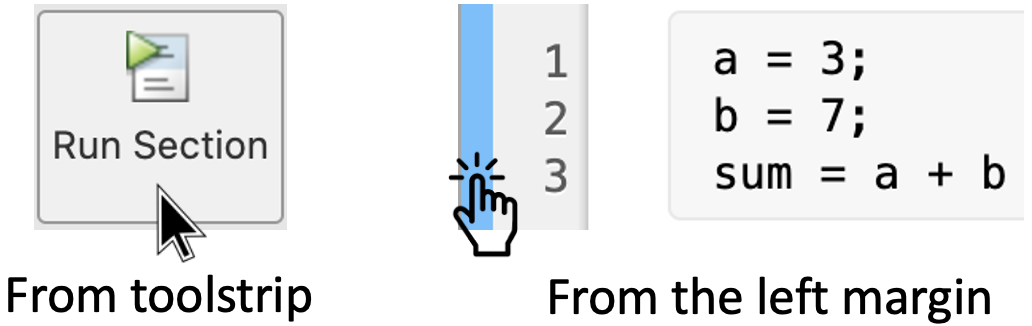

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. The `if` statement

An `if` statement is used to control the execution of a group of commands based on whether a given **condition** is satisfied. At their simplest, they have the following form:

Here, `condition` is a boolean (true/false) expression and `commands` is a set of Matlab commands. When an `if` statement is executed, if `condition` is **true**, then the commands inside the statement (i.e., before the `end` command) are executed; if the condition is **false**, then the commands inside the statement are ignored. 

### 1.1 Example 1: Basic use

For example, consider the following `if` statement:

x =0

if x >= 0          % Set condition
 
    val = x        % Define variable "val" and set it equal to "x"
                   % to display it in the Output view
end

When executed, if `n` is greater than or equal to 0, then the variable `val` is set equal to `x`; if `x` is negative, then nothing happens. Try this yourself! Run this section and then change the value of `n`. Just drag the slider or change its value manually! 

**Remark:** Note that `x` needs to have a value assigned to it before the `if` statement - you cannot compare an empty variable to anything in the condition!

### 1.2 Example 2: The `else` command

In a basic `if` statement, MATLAB does nothing if the condition is false. However, instead of doing nothing, we may want MATLAB to execute a second set of commands when the condition is false. This is done by using the `else` command inside the `if` statement, giving a statement of the following form:

When executed, if the first condition is true, then the first set of commands is executed; if the condition is false, then the second set of commands is executed. 

By adding an `else` command to the previous example, we can make MATLAB execute a series of commands when `x` is negative. For example, run this section to analise the output of the following code:

x = 2

if x >= 0
 
    y = x;
 
else
 
    y = -x;
 
end

y

First notice that the variable `y` was written after the `if-else` statement and the lines 18 and 22 have the semicolon "`;`" at the end, otherwise the value of `y` will be displayed twice.

Now when code is executed, if `x` is greater than or equal to 0, then the variable `y` is set equal to `x`, as before. However, if `x` is negative, then, unlike before where nothing happened, the variable `y` is set equal to `-x`. Thus, the `if` statement sets `y` equal to the absolute value of `x`. 

### 1.3 Example 3: The `elseif` command

The `elseif` command allows us to further modify an `if` statement so that we can execute several sets of commands based on multiple conditions. An `if` statement that uses the `elseif` command has the following form:

When executed, if the first condition is true, then the first set of commands is executed; if the first condition is false and the second condition is true, then the second set of commands is executed; if both the first and second conditions are false, then the third set of commands is executed, and so on. The `elseif` command can be used inside an `if` statement as many times as you like: when executed, as soon as a condition which is satisfied is found, the corresponding command(s) will be executed, and no further conditions are checked.

For example, consider the piecewise function

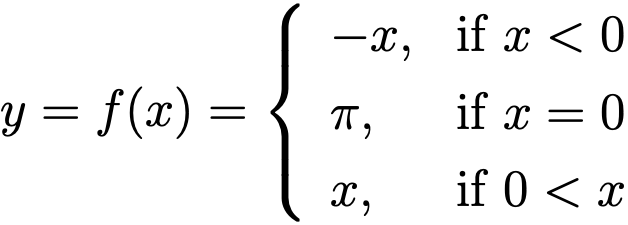

When executed, the following `if` statement will determine whether `x` is negative, positive or zero, and set the variable `y` to the value of f(x) accordingly. Run this section and then drag the slider to change the value of `x`.

x = 0

if x < 0
 
    y = -x;
 
elseif x > 0
 
    y = x;
 
else
 
    y = pi;
 
end

y

### 1.4 Example 4: Logical operators

We can cut down the number of lines in the `if` statement by using [logical operators](https://au.mathworks.com/help/matlab/logical-operations.html). For example we can introduce an OR (`||`) operator and rewrite example 3 as follows:

x = 0

if (x < 0) || (x > 0)  % Check whether x is negative or positive
 
    y = x
 
else
 
    y = pi
 
end

The OR (`||`) operator means that if the condition before the (`||`) is true, OR, the condition after the (`||`) is true, then the whole condition is true.

The AND (`&&`) operator requires that both conditions before or after the (`&&`) must be true for the entire condition to be true.

The NOT (`~`) operator is **not** used in the same way as the AND and OR operators. It is put before a condition to invert the results.

## 2. Hands on practice!

Let's practice what we just learned. 

Using if statements are quite useful for defining our own MATLAB functions. Consider for example the function `sgn` which accepts a real number `x` and returns the value `sgn(x)`, where

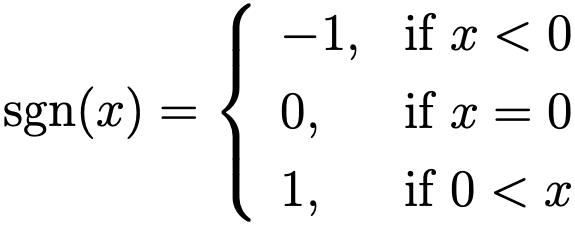

In MATLAB we **must declare a new **[**function**](https://au.mathworks.com/help/matlab/ref/function.html) before using it in our code. In the case of **Live Scripts** we can add it at the very end of our document, see Appendix for more details.

Then we can call our function named sgn to calculate specific values. For example:

sgn(2.97)
sgn(-0.7853)
sgn(-10)
sgn(2^3)
sgn(0)

Run this section! Are these Outputs correct?

## Activity

Write a function called `func` that accepts a real number `x` and returns the value `f(x)`, where

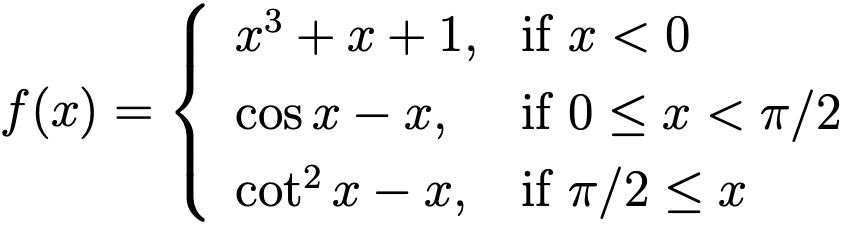

Test your function is correct with the following examples:

- $f\left(-1\right)=-1$,

- $f\left(1\right)=-0\ldotp 4597$,

- $f\left(2\right)=-1\ldotp 7905$.

Then calculate the following:

- 
$$f\left(0\right)$$


- 
$$f\left(-1\ldotp 23\right)$$


- 
$$f\left(\frac{\pi }{2}\right)$$


- 
$$f\left(-2^3 \right)$$


Write your code here:

## Appendix: User-defined functions

function y = sgn(x)    % Define MATLAB function named "sgn"

    if x < 0           % Set 1st condition
        y = -1;        
    elseif x == 0      % Set 2nd condition
        y = 0;
    else               % Set condition for last case. That is, 0 < x.
        y = 1;         
    end
    
end                    % End of function

% Write your function after this line





% Write your function before this line